# Συντάκτες: Γιώργος Τοκατλίδης (58352)

#                   Μιχάλης Τσακίρογλου (58486)             

# 1. Επεξεργασία Ήχου Βραχέως Χρόνου

clear;
clc;

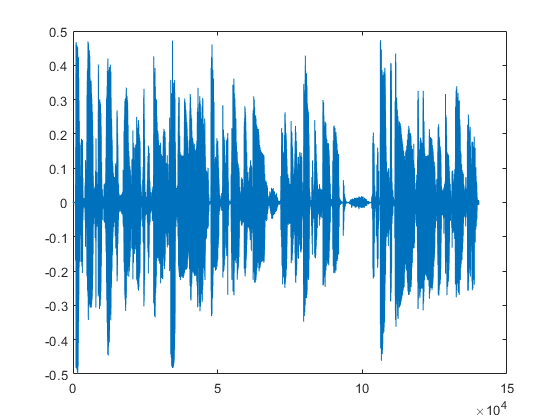

%Read wav file
[x, Fs] = audioread('guit1.wav');

Fs; % = 16000 - sample rate
size(x); % = 140278 samples extracted from wav file

plot(x);

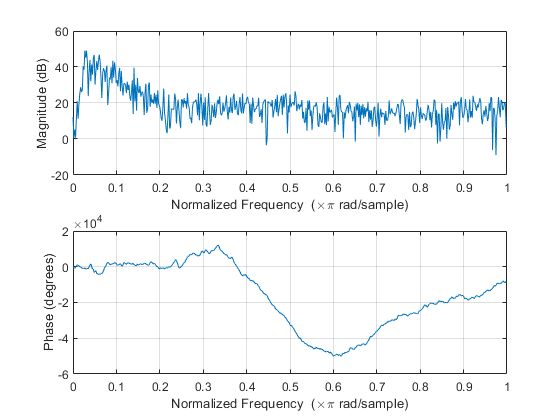

freqz(x);


%test original file
%soundsc(x,16000);

%deconstruct-reconstruct audio file
frame = 256;
ovrlp = 0.5;

X = frame_wind(x,frame,ovrlp);
y = frame_recon(X,ovrlp);

%test de/re-constructed file
%soundsc(y,16000);


# 2. Εντοπισμός Σημείων Εκκίνησης (onsets) νοτών  

α) 

frame = 512;
ovrlp = 0.25; %CAUTION:deixnei poso DEN exoume overlap

[x, Fs] = audioread('piano.wav');

X = frame_wind(x,frame,ovrlp);
[rows, cols] = size(X);

%FFT For every column-frame

XF = fft(X);
XFmag = abs(XF);
XFphase = angle(XF);

*Κάθε στήλη του καινούριο πίνακα XF αντιστοιχεί στον FFT ενός frame του πίνακα Χ. Τη μεταβλητή ****k**** στο ****XF_mag(f, k)**** ή ****XF_ph(f, k)**** τη χρησιμοποιύμε για να προσδιορίσουμε την στήλη που μας απασχολεί. Η μεταβλητή ****f**** αντιπροσωπεύει τη συχνότητα.*

## β)  **Ανιχνευτής Onset με Ενέργεια**

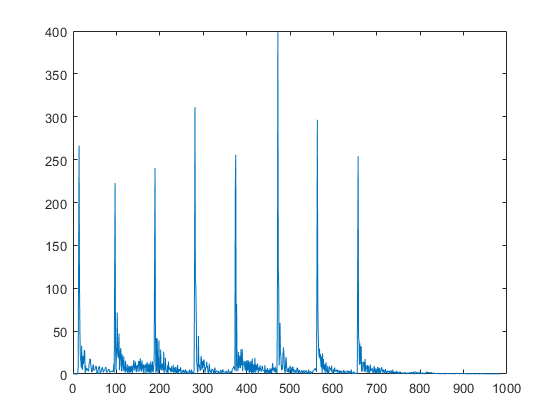

%onset-spike / Energy Method

dE(:,1) = XFmag(:,1); %initialise first dE column outisde loop, to save resources
for f=1:rows
    for k=2:cols
        dE(f,k) = XFmag(f,k) - XFmag(f,k-1);
    end
end

for k=2:cols
    DE(k) = 0;
    for f=1:rows
        DE(k) = DE(k) + dE(f,k);
    end
    DE(k) = abs(DE(k));
end

figure();
plot(DE);

Ο πίνακας DE είναι ένα διάνυσμα που αντιπροσωπεύει το άθροισμα των διαφορών -στο πλάτος- μεταξύ γειτονικών συχνοτήτων για κάθε frame του ηχητικού σήματος.

Κάθε στοιχείο DE(k) του διανύσματος DE αντιπροσωπεύει τη συνολική μεταβολή στο μέγεθος των συνιστωσών συχνότητας μεταξύ των k-1 και k frames του ηχητικού σήματος.

Αναλύοντας το διάνυσμα DE με την πάροδο του χρόνου, μπορούμε να εντοπίσουμε σημαντικές αλλαγές στο ηχητικό σήμα, όπως η έναρξη ενός νέου ηχητικού γεγονότος, η παρουσία σιωπής ή παύσεων.

Επομένως, στο διάγραμμα της DE οι κορυφές που είναι σημαντικά υψηλότερες από τις υπόλοιπες γύρω της, αυτό μπορεί να υποδηλώνει την παρουσία ξαφνικών αλλαγών στο ηχητικό σήμα.

 Από την άλλη πλευρά, εάν η γραφική παράσταση του DE είναι σχετικά επίπεδη, αυτό μπορεί να υποδηλώνει ότι το ηχητικό σήμα είναι σχετικά σταθερό και ομοιόμορφο με την πάροδο του χρόνου.

## γ) Ανιχνευτής Onset με φάση

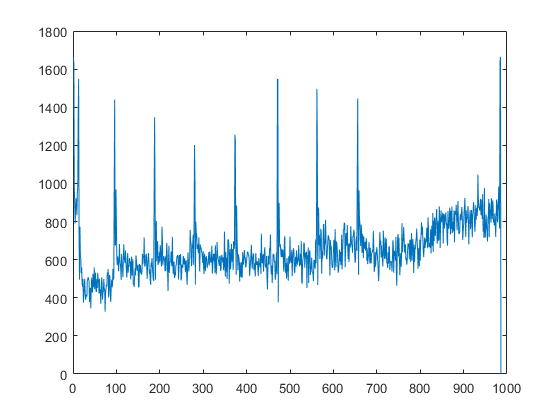


%onset-spike / Phase angle method
dPH1(: ,1) = zeros(rows , 1);
dPH1(: ,2) = wrapToPi(2*XFphase(: ,1));
for f=1:rows
    for k=3:cols
        dPH1(f,k) = wrapToPi(2*XFphase(f,k-1) - XFphase(f,k-2));
    end
end

for f=1:rows
    for k=1:cols
        dPH(f,k) = wrapToPi(XFphase(f,k) - dPH1(f,k));
    end
end

for k=1:cols
    DPH(k) = 0;
    for f=1:rows
        DPH(k) = DPH(k) + (abs(dPH(f,k)))^2;
    end
end

figure();
plot(DPH);

## γ) Ανιχνευτής Onset με Μιγαδικούς

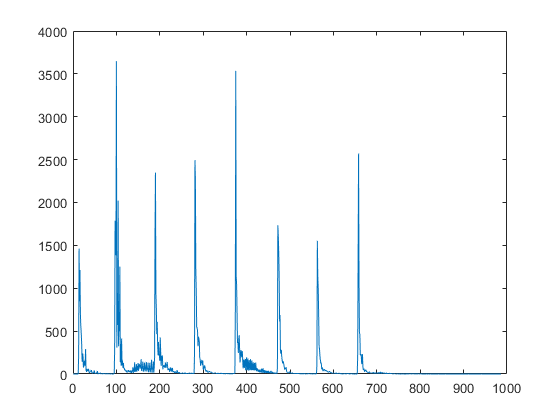


%complex numbers method

dC(:,1) = XF(:,1);
for f=1:rows
    for k=2:cols
        dC(f,k) = XF(f,k) - (XFmag(f,k-1))*exp(1j*dPH1(f,k));
    end
end

for k=1:cols
    DC(k) = 0;
    for f=1:rows
        DC(k) = DC(k) + (abs(dC(f,k)))^2;
    end
end

figure();
plot(DC);

# 3. Υπολογισμός του ρυθμού bpm ενός κομματιού 

**Λίγα λόγια:**

Σκοπός αυτού του σκέλους, είναι να αποτυπώσει για διαφορετικά ποσοστά επικάλυψης μεταξύ frames, την αποδοτικότητα των τριών διαφορετικών Ανιχνευτών Incident - Onset καθώς και την αξιοπιστία τους πάνω σε διαφορετικά δοκιμαστικά μουσικά snippets, στα οποία μπορεί να διαφέρει το κυρίαρχο - leading μουσικό όργανο. Ως leading όργανο ορίζουμε για την άσκηση αυτό που "ξεχωρίζει" περισσότερο από τα υπόλοιπα, επειδή ορίζει σαφέστερα την αίσθηση του ρυθμού. Είναι σημαντικό να αναφέρουμε πως η ηχητική επικράτηση διαφορετικού μουσικού οργάνου, μπορεί να χρήζει ανάγκη διαφορετικής αντιμετώπισης λόγω των διαφορετικών συχνοτικών φύσεων του καθενός, για αυτό και πρέπει να δοκιμαστούν οσο το δυνατόν περισσότερα αρχεία γίνεται.

Για τις ανάγκες της άσκησης, θα χρησιμοποιηθούν τα τρία δεδομένα wav αρχεία : "piano.wav", "seven_nation army.wav", "insomnia.wav".

Θα παρατίθενται για κάθε ποσοστό επικάλυψης τα bpm που προκύπτουν από τη ρουτίνα peak_pickingGT, με χρήση της DE, DPH και DC αντίστοιχα.

Σημείωση : Ο δείκτης ovrlp δείχνει το ποσοστό ΜΗ επικάλυψης μεταξύ των frame, αφού αυτό προκύπτει από τις ρουτίνες που δίνονται.

a)

#### 
$$R_{\textrm{DE}} \left(\tau \right)=\sum_{\kappa =1}^{N_{\kappa } } \textrm{DE}\left(\kappa \right)\textrm{DE}\left(\kappa -\tau \right)=\textrm{DE}\left(\tau \right)*\textrm{DE}\left(-\tau \right)$$


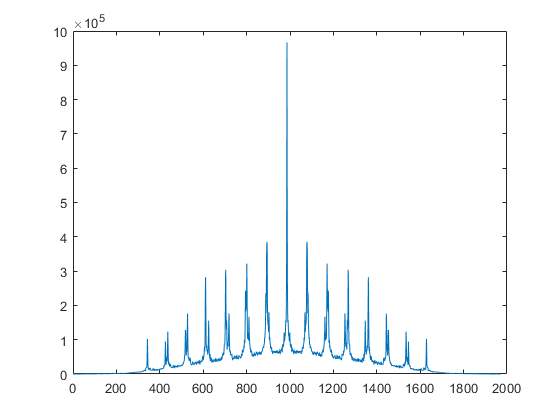

R_DE = xcorr(DE, DE);
figure();
plot(R_DE)

 
[X_Point distance] = peak_pickingGT(R_DE, length(R_DE))

X_Point = 1078

distance = 92


%Frame distance to BPM Conversion

Η μεθοδολογία που ακολουθάμε για να μετατρέψουμε την απόσταση αυτή σε BPM είναι η εξής:

- Υπολογίζουμε τα συνολικά δείγματα που είναι ίσα με το γινόμενο απόστασης*frames*ποσοστoύ_επικάλυψης.

- Βρίσκουμε σε πόσο χρόνο αντιστοιχούν τα δείγματα αυτα με μέθοδο τριών(1sec -> 16000 δείγματα, x sec -> Samples ).

- Αντιστρέφουμε το χρόνο που βρήκαμε ώστε να υπολογίσουμε τη συχνότητα που πρακτικά είναι ισοδύναμη με το μέγεθος bps(beats per second) και το πολλαπλασιάζουμε με 60 για να το μετατρέψουμε σε bpm.

%Frames to samples
Samples = distance*frame*ovrlp;
BPM(1) = (Fs/Samples)*60 

BPM = 81.5217

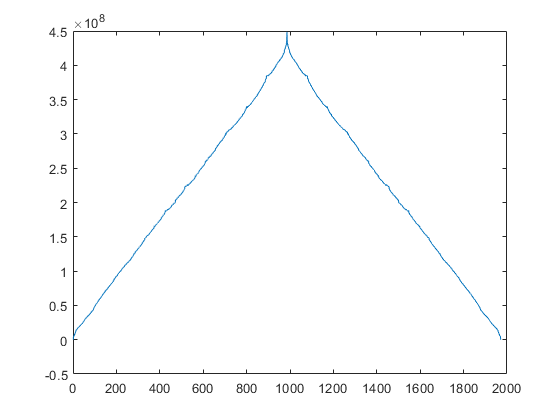


%Same for DPH
R_DPH = xcorr(DPH, DPH);
figure();
plot(R_DPH)


[X_Point distance] = peak_pickingGT(R_DPH, length(R_DPH))

X_Point = 989

distance = 3


Samples = distance*frame*ovrlp;
BPM(2) = (Fs/Samples)*60

BPM = 	1.0e+03 *

    0.0815    2.5000


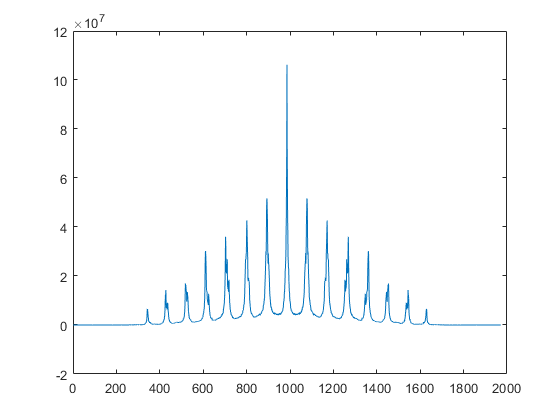


%Same for DC
R_DC = xcorr(DC, DC);
figure();
plot(R_DC)


[X_Point distance] = peak_pickingGT(R_DC, length(R_DC))

X_Point = 1078

distance = 92


Samples = distance*frame*ovrlp;
BPM(3) = (Fs/Samples)*60

BPM = 	1.0e+03 *

    0.0815    2.5000    0.0815


### Οι μετρήσεις που χρησιμοποιήθηκαν για να εξάγουμε τα συμπεράσματα:

**1ο δοκιμαστικό αρχείο**: "piano.wav"

Original BPM : *80 bpm*

Για ovrlp = 1 : 81.5217  81.5217  81.5217

Για ovrlp = 0.75 : 80.6452  80.6452  80.6452

Για ovrlp = 0.5 : 79.7872  81.5217  81.5217  

Για ovrlp = 0.25 : 81.5  2500  81.5

**2ο δοκιμαστικό αρχείο**: "seven_nation_army.wav"

Original BPM : *125 bpm*

Για ovrlp = 1 : 125  NA  125 - σφάλμα στην peak_pickingGT για DPH

Για ovrlp = 0.75 : NA  NA  NA - σφάλμα στην frame_wind

Για ovrlp = 0.5 : 125  NA  125 - σφάλμα στην peak_pickingGT για DPH

Για ovrlp = 0.25 : 125  1875 125 

**3ο δοκιμαστικό αρχείο**: "insomnia.wav"

Original BPM : *128 / 64(half-time)* bpm

Για ovrlp = 1 : 31.78 NA  125 - σφάλμα στην peak_pickingGT για DPH

Για ovrlp = 0.75 : NA  NA  NA - σφάλμα στην frame_wind

Για ovrlp = 0.5 : 63.56  NA  63.56 - σφάλμα στην peak_pickingGT για DPH

Για ovrlp = 0.25 : 63.6 1875 63.6

d)

**Γενικά σχόλια και παρατηρήσεις**: Για τα αρχεία που δοκιμάστηκαν οι μέθοδος ενέργειας και μιγαδικών αριθμών στάθηκαν πιο robust και αξιόπιστοι. Δεν υπάρχει αμφιβολία πως η μέθοδος φασικής γωνίας είναι λιγότερο αποτελεσματική και κατά τη διάρκεια των δοκιμών προκαλούσε σφάλματα στις έτοιμες ρουτίνες και τη ρουτίνα που κληθήκαμε οι ίδιοι να συνθέσουμε. Οι αποκλίσεις μεταξύ 1ης και 3ης μεθόδου είναι μηδενικές εκτός από μια μέτρηση στο 1ο και 3ο αρχείο. Από αυτές τις 2 αποκλίσεις φαίνεται πως η 3η μέθοδος είναι αποτελεσματικότερη. Ακόμα και διαισθητικά ωστόσο θα μπορούσε κανείς να υποθέσει παρατηρώντας τις κυματομορφές των μεθόδων για το 1ο δοκιμαστικό αρχείο πως η μέθοδος μιγαδικών αριθμών είναι η πιο ασφαλής οδός, επειδή δίνει πολύ καθαρότερη εικόνα για τα incident, το attack και decay της νότας.

Η ρουτίνα **“frame_wind” **διαιρεί μια κυματομορφή ήχου σε μικρότερα παράθυρα με επικάλυψη. Η ρουτίνα παίρνει ως μεταβλητές εισόδου i) τη διακριτή κυματομορφή ήχου x, ii) το μέγεθος του παραθύρου σε πλήθος δειγμάτων frame, iii) το ποσοστό του παραθύρου στο οποίο θα γίνεται η επικάλυψη ovrlp (από 0 ως 1, default = 0.5). H έξοδος της ρουτίνας είναι ένας πίνακας X, κάθε στήλη του οποίου περιέχει τα παράθυρα που έχουμε εξάγει με τη σειρά εξαγωγής.

function X=frame_wind(x,frame, ovrlp)   

    M=length(x);
    K=floor(M/(frame*ovrlp));
    X=zeros(frame,K);
    W=hann(frame);
    for i=1:K-floor(1./ovrlp-1)
        indx=(i-1)*floor(frame*ovrlp);
        X(:,i)=x(indx+1:indx+frame).*W;
    end 
end

Η ρουτίνα **“*****frame_recon*****”** ανακατασκευάζει μια κυματομορφή ήχου από τα μικρότερα παράθυρα με επικάλυψη από τον πίνακα Χ. Παίρνει ως μεταβλητές εισόδου i) τον πίνακα Χ ii) το ποσοστό του παραθύρου, στο οποίο θα γίνεται η επικάλυψη ovrlp (default = 0.5).

function y=frame_recon(X, ovrlp)   

    [frame, K]=size(X);
    
    Mmax=K+floor(1./ovrlp-1);
    
    y=zeros(1,frame*Mmax*ovrlp);
    for i=1:K
        indx=(i-1)*floor(frame*ovrlp);
        y(indx+1:indx+frame)=y(indx+1:indx+frame)+X(:,i)';
    end 
end

b) Η ρουτίνα **"peak_pickingGT" **αποσκοπεί στον εντοπισμό των κορυφών σε ένα δεδομένο σήμα, επιστρέφει τον δείκτη της υψηλότερης κορυφής και την απόστασή της από το κέντρο του σήματος. Παίρνει ως μεταβλητές εισόδου 1) τη συνάρτηση αυτοσυσχέτισης 2) το μήκος της συνάρτησης αυτής. 

Αρχικά υπολογίζουμε το κέντρο της κυματομορφής. Έπειτα επείδη μας ενδιαφέρει η δεύτερη μεγαλύτερη κορυφή δεξιά της DE ξεκινάμε το βρόχο επανάληψης από το αμέσως επόμενο σημείο απο το κέντρο και αρχίζουμε να αναζητούμε τα τοπικά μέγιστα. Ο υπολογισμός του τ.μ γίνεται με τον εξής τρόπο: συγκρίνουμε ένα σημείο με το αμέσως προηγούμενο και το αμέσως επόμενο του, προυπόθεση για να είναι τ.μ είναι να είναι μεγαλύτερο και από τα δύο. Η τιμή της κάθε κορυφής αποθηκεύεται στον πίνακα R_DEmaximas και τα Χ που δίνουν τα αντίστοιχα ακρότατα στον πίνακα R_DEpeakpoints, με δείκτη m. Στη συνέχεια, ταξινομούμε την R_DEmaximas κατά φθίνουσα σειρά (για λόγους ευκολίας)  και o πίνακας sorted_peakpoints κρατά τους δείκτες m των ταξινομημένων ακροτάτων, δηλαδή τη θέση του ακρότατου μέσα στον πίνακα R_DEmaximas(ή αλλιώς τα διαφορετικά m) και με σειρά που ορίζεται από τη sorted_maximas. Άρα 1ο στοιχείο του είναι το index της μεγαλύτερης κορυφής του R_DEmaximas, το 2ο στοιχείο είναι το index της 2ης μεγαλύτερης κορυφής του R_DEmaximas κ.ο.κ. Έτσι, ο δείκτης m της υψηλότερης κορυφής είναι το 1ο στοιχείο του sorted_peakpoints και ανατίθεται στη μεταβλητή index. Το αποτέλεσμα της R_DEpeakpoints (με όρισμα το index) το περνάμε στο X_Point. Αυτό θα είναι και το original Χ value του ακρoτάτου που ψάχνουμε.

Τέλος, υπολογίζουμε την απόσταση μεταξύ της επιλεγμένης κορυφής και του κέντρου του σήματος, το οποίο επιστρέφεται ως απόσταση(distance).

function [X_Point, distance] = peak_pickingGT(R_DE, R_DE_length)

center = floor(R_DE_length/2) + 1; % floor: Round toward negative infinity

m = 1;
for i = center+1 : R_DE_length-1
    if (R_DE(i) > R_DE(i-1)) && (R_DE(i) > R_DE(i+1))
        R_DEmaximas(m) = R_DE(i);
        R_DEpeakpoints(m) = i;
        m = m+1;
    end
end

[sorted_maximas, sorted_peakpoints] = sort(R_DEmaximas, 'descend');
index  = sorted_peakpoints(1);
X_Point = R_DEpeakpoints(index);

% Find the distance between second peakpoint and center of RDE
distance = abs(X_Point - center);

end